# BEV System Model - Simulation Case

modelName = "BEV_system_model";
load_system(modelName)
% Use thermal-model-enabled components.
BEV_useComponents_Thermal

Use thermal models for Motor Drive Unit and High Voltage Battery components.


VehSpdRef_loadSimulationCase_SimpleDrivePattern( ...
  ModelName = modelName, ...
  TargetSubsystemPath = ...
    "/Controller & Environment" + ...
    "/Vehicle speed reference" )

Setting up simulation...
Simulation case: Simple drive pattern
Setting simulation stop time to 100 sec.
Selecting simulation case 1.


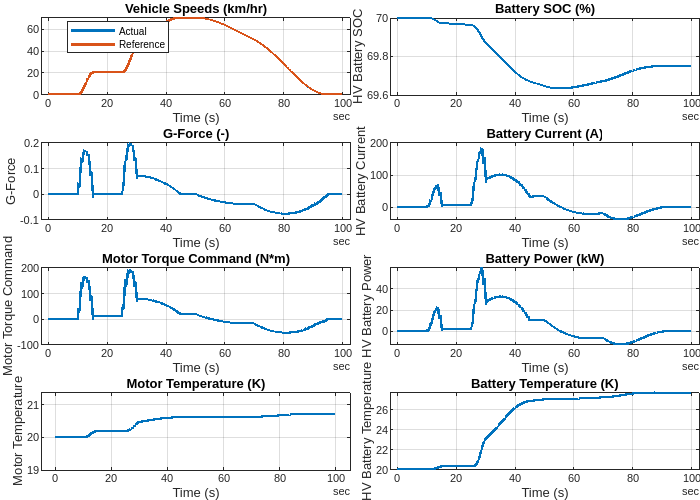

simOut = sim(modelName);
simData = extractTimetable(simOut.logsout);
fig = BEV_plotResultsCompact( SimData = simData );

*Copyright 2023 The MathWorks, Inc.*